# Compund pendulum

Physics lab 1 exam

manca da calcolare rappresentare g con la propagazione degli errori.

% cleaning
clc
clear

% importing data
df1=readtable("..\data\new-exp-data-1.csv");
df2=readtable("..\data\new-exp-data-2.csv");
% test round
% df2.time_ms = round(df2.time_ms,-1);

tools=readtable("..\data\tools.csv");
% count configurations
uc=unique(df2.configuration); % unique configuration
nc=length(uc);                % number of configs

## Prima esplorazione e distribuzione delle misure indirette

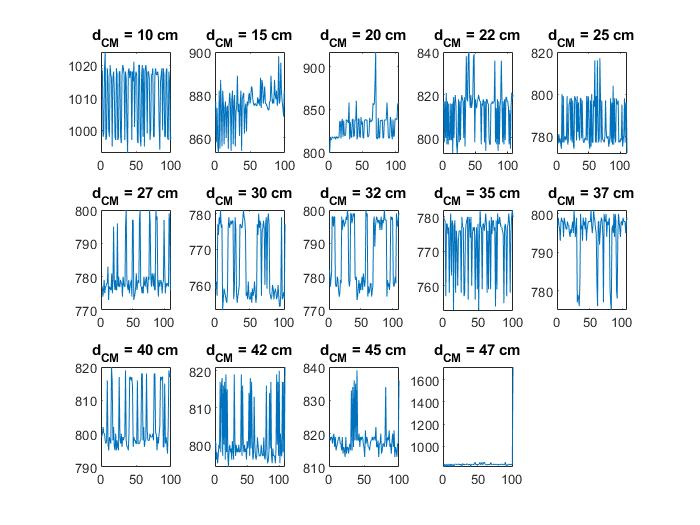

% line chart
linechart=figure;
for i=1:nc
    subplot(3,5,i)
    plot(table2array(df2(df2.configuration==uc(i),"event")),table2array(df2(df2.configuration==uc(i),"time_ms")))        
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

Noto comportamento anomalo per d_cm = 47 configurazione 14. Esploro in seguito

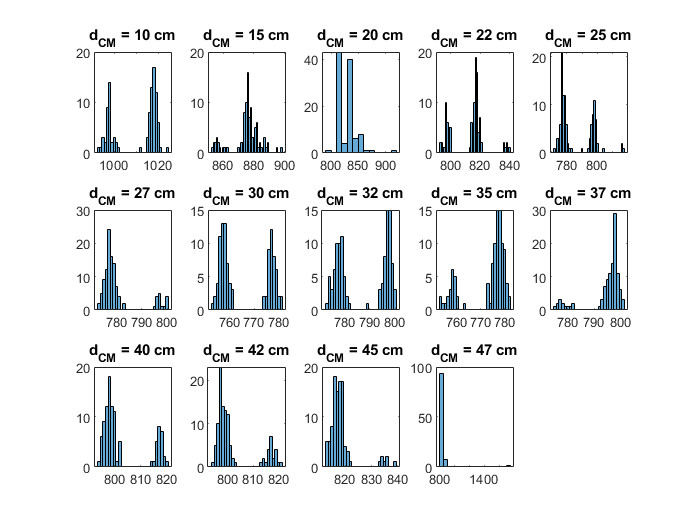

% histogram
hst=figure;
for i=1:nc
    subplot(3,5,i)
    histogram(table2array(df2(df2.configuration==uc(i),"time_ms")))     
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

## Qual è l'incertezza sui tempi?

Per stimarla, calcolo la deviazione standard sui tempi per ogni configurazione

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
% dev.ratio = round((dev.deviation./dev.mean_ms).*100,2);

dev = 14×4 table
    configuration    mean_ms    deviation    ratio
    _____________    _______    _________    _____

          1           1010         10         0.99
          2            875          9         1.03
          3            831         16         1.93
          4            813         11         1.35
          5            786         11          1.4
          6            780          7          0.9
          7            766         10         1.31
          8            787         10         1.27
          9            773          9         1.16
         10            795          6         0.75
         11            803          8            1
         12            802          8            1
         13            818          5         0.61
         14            845         88        10.41


## Rigetto di dati

% calcolo distanza dalla media in valore assoluto per ogni valore

ans = 1×4 table
    configuration    mean_ms    deviation    ratio
    _____________    _______    _________    _____

         14            845         88        10.41



% join con dev per ottenere tempi medi (mean_ms)
df2 = join(df2,dev,"Keys","configuration");
df2 = df2(:,["configuration","event","time_ms","mean_ms","deviation"]);
df2.difference = abs(df2.time_ms - df2.mean_ms);

% calcola di quante deviazioni standard il valore è fuori
df2.out = round(df2.difference ./ df2.deviation,1);

% filter out
df2 = df2(df2.out <= 3.5,:)

df2 = 1457×7 table
    configuration    event    time_ms    mean_ms    deviation    difference    out
    _____________    _____    _______    _______    _________    __________    ___

          1            1       1019       1010         10             9        0.9
          1            2       1018       1010         10             8        0.8
          1            3        998       1010         10            12        1.2
          1            4        999       1010         10            11        1.1
          1            5       1019       1010         10             9        0.9
          1            6       1024       1010         10            14        1.4
          1            7        997       1010         10            13       

% aggiorno variabili
uc=unique(df2.configuration) % unique configuration

uc =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


nc=length(uc)                % number of configs

nc = 14

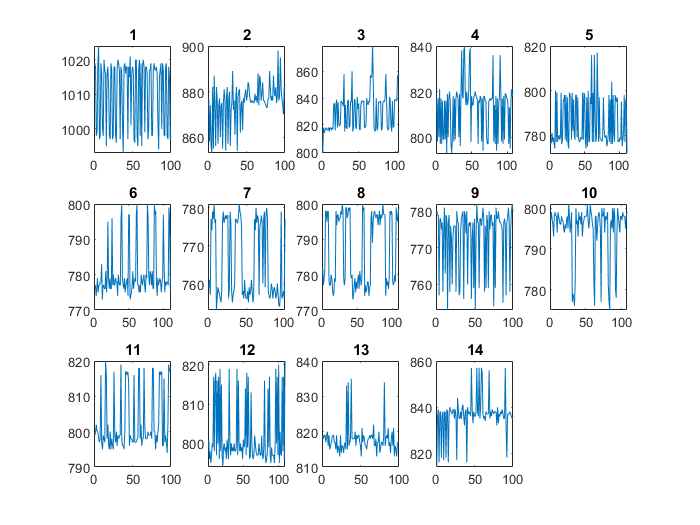

%linechart dopo chauvenet
figure
for i=1:nc
    subplot(3,5,i)
    plot(table2array(df2(df2.configuration==uc(i),"event")),table2array(df2(df2.configuration==uc(i),"time_ms")))        
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    % title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(string(table2array(df1(df1.configuration==uc(i),"configuration"))))
end

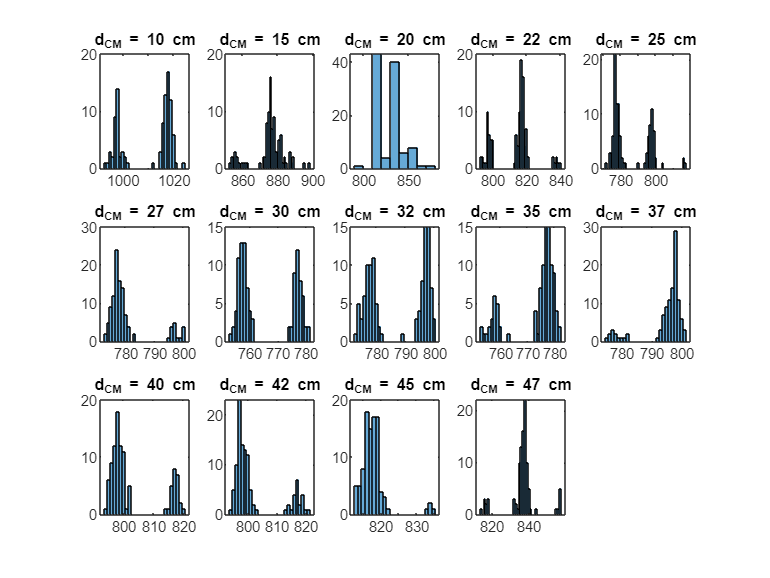

% histogram
hst=figure;
for i=1:nc
    subplot(3,5,i)
    histogram(table2array(df2(df2.configuration==uc(i),"time_ms")))     
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

## seleziono dati

df2(df2.configuration == 1 & )

Alla luce dell'applicazione del criterio di Chauvenet, ricalcolo media e deviazione

% delete old mean and deviation
df2 = df2(:,["configuration", "event", "time_ms"]);

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
% dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
% dev.ratio = round((dev.deviation./dev.mean_ms).*100,2)

% defining variable
uc=unique(df2.configuration) % unique configuration

uc =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


nc=length(uc)                % number of configs

nc = 14

l=1;                          % pendulum length
g=9.81;                       % gravitational acceleration
dg=0.01;                      % error gravitational acceleration
dt=tools.uncertainty(1);      % error t
dr=tools.uncertainty(2);      % errror distance

% overwrite distance error
dr = 0.002; % meters

% creating empty array
tm=zeros(nc,1);     % tempi medi
dtm=zeros(nc,1);    % error t
d=zeros(nc,1);      % distance from CM
dd=zeros(nc,1);     % error distance
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(nc,1);     % gravitational acceleration calculated
dgc=zeros(nc,1);    % error gc
regc=zeros(nc,1);   % relative error gravitational acceleration
cfrg=zeros(nc,1);   % position first significant digit gravitational acceleration
uomd=string(zeros(nc,1));   % uom distance
uomg=string(zeros(nc,1));   % uom g
uomt=string(zeros(nc,1));   % uom t

% multiply *2, converting ms2s and rounding
% df2.period_s=round(df2.time_ms.*2./1000,1)
df2.period_s=df2.time_ms*2/1000

df2 = 1457×4 table
    configuration    event    time_ms    period_s
    _____________    _____    _______    ________

          1            1       1019       2.038  
          1            2       1018       2.036  
          1            3        998       1.996  
          1            4        999       1.998  
          1            5       1019       2.038  
          1            6       1024       2.048  
          1            7        997       1.994  
          1            8        998       1.996  
          1            9       1019       2.038  
          1           10       1016       2.032  
          1           11       1000           2  
          1           12        998       1.996  
          1           13       1020        2.04  
          1           14       1017       2.034  
          1           15       1016       2.

dt = 2*dt

dt = 0.1000

## Propagazione degli errori

% core
for i=1:nc
    % calculating mean
    tm(i)=mean(table2array(df2(df2.configuration==uc(i),"period_s")));
    
    % error t
    dtm(i)=dt;
    
    % distance from CM
    d(i)=table2array(df1(df1.configuration==uc(i),"distance_cm"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %convering cm2m
    
    % error distance from CM
    dd(i)=dr;
    
    % calculating gravitational acceleration
    gc(i)=(l.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    
    % propagation of error g
%     cfrg(i)=-floor(log10(dgc(i)));  % position first significant digit g
%     dgc(i)=round(dgc(i),cfrg(i));   % round dgc
%     gc(i)=round(gc(i),cfrg(i)+1);   % round g calculated
    
    % relative error g
    regc(i)=round(dgc(i)./gc(i)*100,2);
    
    % unit of measure
    uomd(i)="MTR";
    uomg(i)="MSK";
    uomt(i)="SEC";
end

% significant digits time
cfrt=-floor(log10(dt));         % position first significant digit time
tm=round(tm,cfrt);              % round

% mean gravitational acceleration (output3)
% gm=round(mean(gc(2:10)),1);
% dgm=round(mean(dgc(2:10)),0);
% regm=round((dgm/gm)*100,2);

% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l.^2)./(12.*r))+r);

% chi
chio1 = sum((tm-teot(1,d)./dtm).^2)

chio1 = 2.8702e+03

il chi quadro 2.8702e+03 cioè di 2870 è più del doppio del numero di misure effettuate. Questo è un cattivo segno.

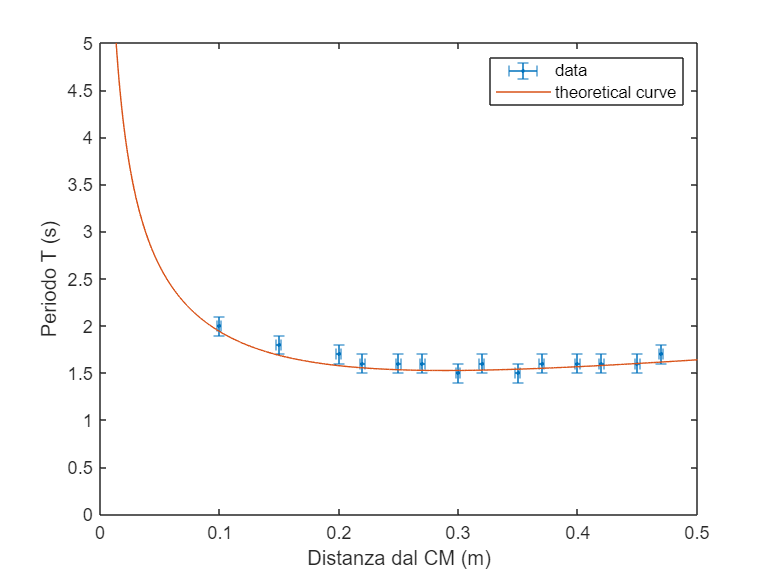

% plotting

plt1=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,5])
xlim([0.0 0.5])
legend('data','theoretical curve')

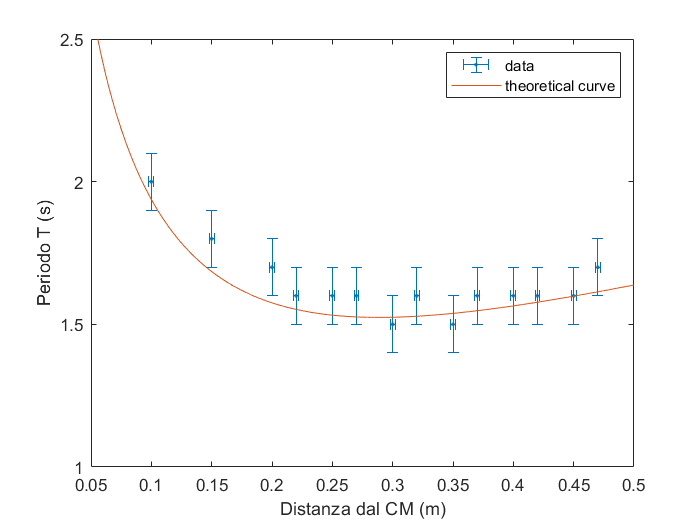


plt2=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([1 2.5])
xlim([0.05 0.5])
legend('data','theoretical curve')

## Analisi statistica

Una parte di analisi statistica è stata fatta all'inizio di questo notebook. 

Potrei spostare questa parte in alto (dopo il rigetto dei dati)

% calcolo gc2 con formula più corta (g calculated 2)
% for i = 1:nc
%     gc2(i) = (2.*pi./tm(i)).^2  .*  ((l.^2)/(12.*d(i)) + d(i));
% end

% T function of d with standard deviation

tt=(2.*pi./sqrt(g)).*sqrt(((l.^2)./(12.*r))+r); % theoretical curve

for i = 1:nc
    tm(i) = mean(table2array(df2(df2.configuration == uc(i),"period_s")));
    sigma_t(i) = std(table2array(df2(df2.configuration == uc(i),"period_s")));
end

o4 = table(uc,tm,sigma_t','VariableNames',{'configuration','mean_period','sigma_t'})

o4 = 14×3 table
    configuration    mean_period     sigma_t 
    _____________    ___________    _________

          1            2.0203        0.019995
          2            1.7504        0.018007
          3            1.6602        0.028204
          4            1.6253         0.02253
          5            1.5717        0.021802
          6            1.5606        0.014744
          7            1.5318        0.020136
          8             1.575        0.020012
          9             1.546        0.017468
         10            1.5897        0.012995
         11            1.6057        0.016984
         12            1.6041        0.016019
         13            1.6356       0.0078067
         14            1.6733        0.016511


% rounding
o4.mean_period = round(o4.mean_period,2);
o4.sigma_t = round(o4.sigma_t,2);

% join o4 with df1 in order to obtain distance
o4 = join(o4,df1,"Keys","configuration");
o4.distance_m = (o4.distance_cm-50)/100;

% filter out distance_cm
o4 = o4(:,["configuration","mean_period","sigma_t","distance_m"]);

% compute teoretical period
o4.teo_period = teot(1,o4.distance_m);

% preview
o4

o4 = 14×5 table
    configuration    mean_period    sigma_t    distance_m    teo_period
    _____________    ___________    _______    __________    __________

          1             2.02         0.02          0.1          1.938  
          2             1.75         0.02         0.15          1.685  
          3             1.66         0.03          0.2         1.5753  
          4             1.63         0.02         0.22         1.5523  
          5             1.57         0.02         0.25         1.5322  
          6             1.56         0.01         0.27          1.526  
          7             1.53         0.02          0.3         1.5248  
          8             1.57         0.02         0.32         1.5283  
          9             1.55         0.02         0.35         1.5384  
         10          

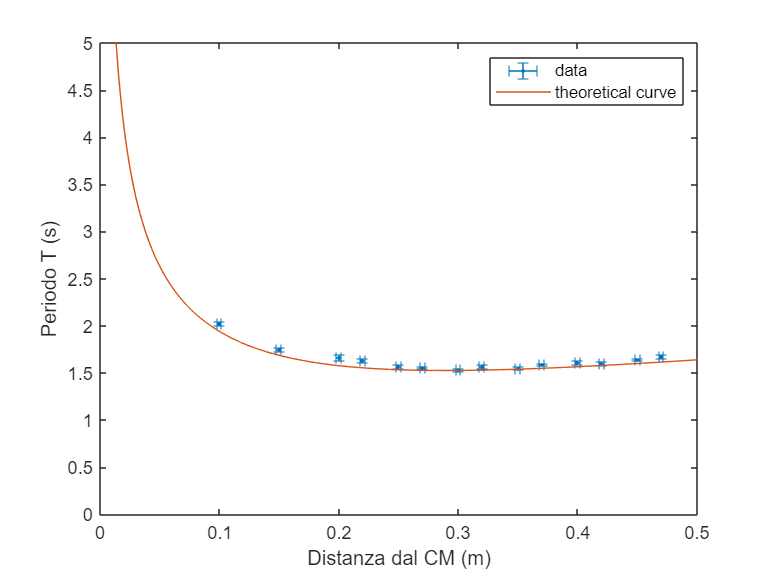

% plotting
plt3=figure;
errorbar(d,o4.mean_period,o4.sigma_t,o4.sigma_t,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
ylim([0 5])
hold on
plot(r,tt)
hold off
legend('data','theoretical curve')

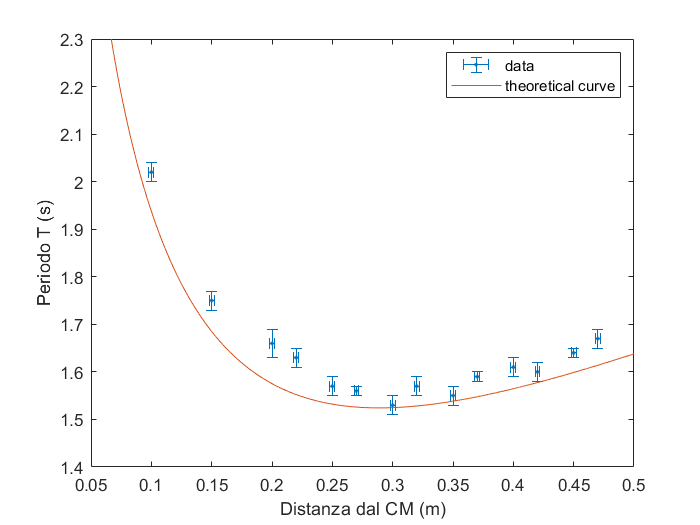

plt4=figure;
errorbar(d,o4.mean_period,o4.sigma_t,o4.sigma_t,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([1.4 2.3])
xlim([0.05 0.5])
legend('data','theoretical curve')


% calcolare chi quadro su questo grafico
% compute chi square
chio4 = sum(((o4.mean_period-o4.teo_period)./o4.sigma_t).^2)

chio4 = 119.3972

% chi ridotto
chio4./(height(o4)-1)

ans = 9.1844

## Metodo dei minimi quadrati

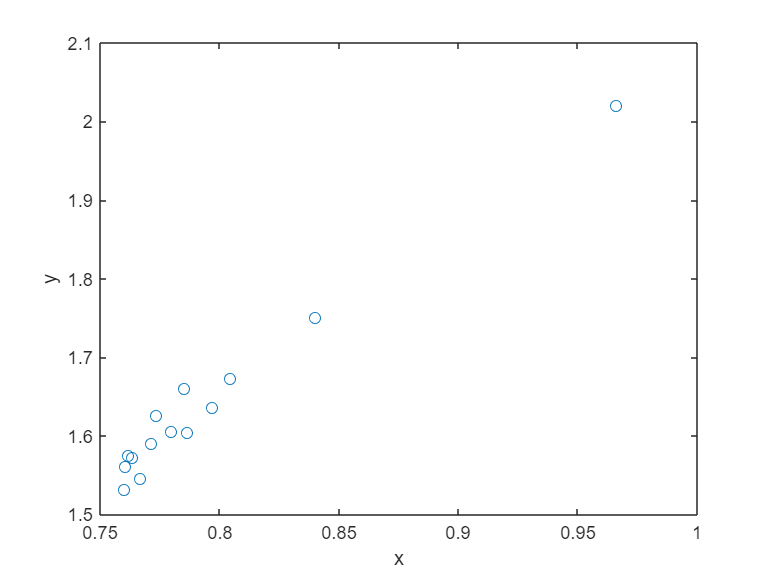

y = tm;
x = sqrt(  (repelem(l,length(d))'.^2)./(12.*d) + d   );

% plot y and x
plot(x,y,'o')
xlabel("x")
ylabel("y")

% determino parametri per applicare metodo minimi quadrati

% numero di punti
n = length(tm);

delta = n.*sum(x.^2) - (sum(x)).^2;

% intercetta
a = (   (sum(x.^2).*sum(y))  - (sum(x).*sum(x.*y))   )./delta

a = -0.1540


% coefficiente angolare
b = (   (n.*sum(x.*y)) - (sum(x).*sum(y))   )./delta

b = 2.2582

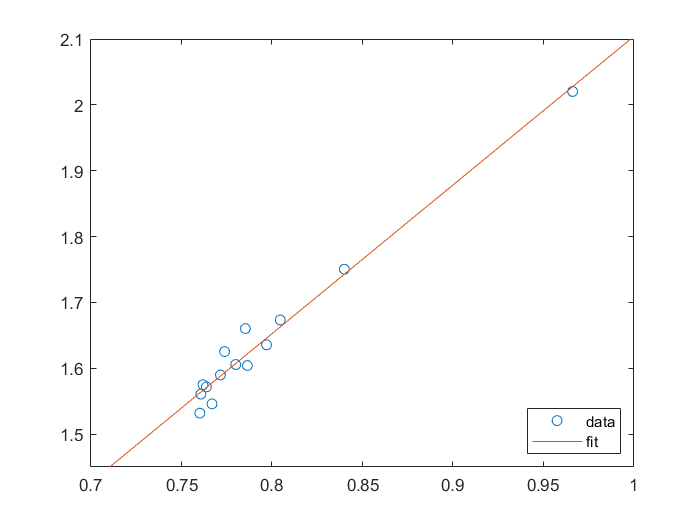


figure
plot(x,y,'o')
hold on
plot(0:1,a+b.*(0:1)')
hold off
legend("data","fit",'Location','southeast')
xlim([0.7 1])
ylim([1.45 2.1])

% stimo g dal coefficiente angolare
% gmq sta per "g minimi quadrati"
gmq = (2.*pi./b).^2

gmq = 7.7420

gmq2 = (2.*pi./(2.05)).^2

gmq2 = 9.3940

## Determino g (analisi statistica)

% join df1 e df2
df2 = join(df2,df1,"Keys","configuration");
df2.distance_cm = df2.distance_cm - 50;
df2.distance_m = df2.distance_cm/100;
df2 = df2(:,["configuration","event","period_s","distance_m"]);

% calculate g
for i = 1:height(df2)
    df2.g_calc(i) = (2.*pi./df2.period_s(i)).^2  .*  ((l.^2)/(12.*df2.distance_m(i)) + df2.distance_m(i));
end

% preview 
df2

df2 = 1457×5 table
    configuration    event    period_s    distance_m    g_calc
    _____________    _____    ________    __________    ______

          1            1       2.038         0.1        8.8713
          1            2       2.036         0.1        8.8888
          1            3       1.996         0.1        9.2486
          1            4       1.998         0.1        9.2301
          1            5       2.038         0.1        8.8713
          1            6       2.048         0.1        8.7849
          1            7       1.994         0.1        9.2672
          1            8       1.996         0.1        9.2486
          1            9       2.038         0.1        8.8713
          1           10       2.032         0.1        8.9238
          1           11           2         0.1      


% calculate mean and standard deviation of g
for i = 1:nc
    g_calc_mean(i) = mean(table2array(df2(df2.configuration == uc(i),"g_calc")));
    g_sigma(i) = std(table2array(df2(df2.configuration == uc(i),"g_calc")));
end

o5 = table(uc,g_calc_mean',g_sigma','VariableNames',{'configuration','g','sigma'})

o5 = 14×3 table
    configuration      g        sigma 
    _____________    ______    _______

          1          9.0299       0.18
          2          9.0937    0.18957
          3          8.8398    0.29586
          4          8.9536    0.24837
          5          9.3282    0.25477
          6          9.3815    0.17288
          7          9.7266    0.25429
          8          9.2418    0.23507
          9           9.718    0.22408
         10          9.3001    0.15591
         11          9.3181     0.1939
         12          9.4909    0.18591
         13          9.3739    0.08772
         14          9.1299     0.1812


% rounding
o5.g = round(o5.g,1);
o5.sigma = round(o5.sigma,1);

% preview
o5

o5 = 14×3 table
    configuration     g     sigma
    _____________    ___    _____

          1            9     0.2 
          2          9.1     0.2 
          3          8.8     0.3 
          4            9     0.2 
          5          9.3     0.3 
          6          9.4     0.2 
          7          9.7     0.3 
          8          9.2     0.2 
          9          9.7     0.2 
         10          9.3     0.2 
         11          9.3     0.2 
         12          9.5     0.2 
         13          9.4     0.1 
         14          9.1     0.2 


% chi quadro
cg = sum(((o5.g-repelem(9.81,height(o5))')./o5.sigma).^2)

cg = 118.3939

% mean g
round(mean(o5.g),1)

ans = 9.3000

mean(o5.sigma)

ans = 0.2143

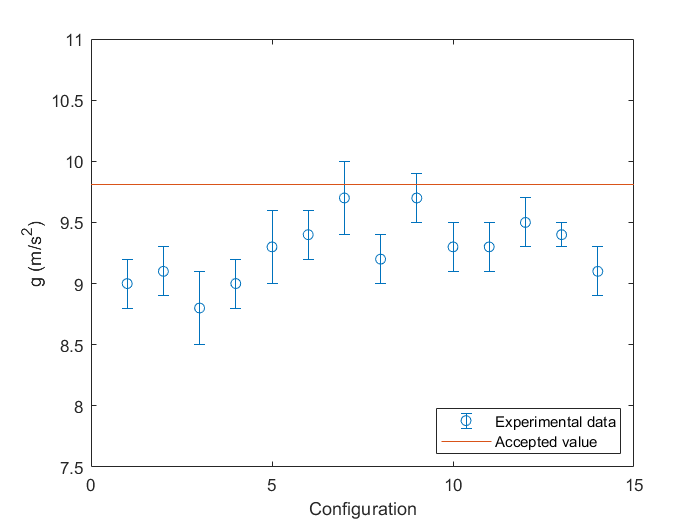

% plotting
plt5=figure;
errorbar(o5.configuration,o5.g,o5.sigma,'o')
hold on
plot(0:length(o5.configuration)+1,repelem(9.81,length(0:length(o5.configuration))+1,1))
hold off
xlim([0 height(o5)+1])
ylim([7.5 11])
legend("Experimental data","Accepted value","Location","southeast")
xlabel("Configuration")
ylabel("g (m/s^2)")

## Exporting

% converting array to string
% d=string(d);
% tm=string(tm);
% gc=string(gc);
% regc=string(regc);
% 
% for i=1:nc
%     d(i)=sprintf('%.3f',d(i));
%     tm(i)=sprintf('%.2f',tm(i));
%     gc(i)=sprintf('%.1f',gc(i));
%     regc(i)=sprintf('%.2f',regc(i));
% end

% generating output 1
% output1=array2table(cat(2,string(uc),d,gc,dgc,regc,uomg),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error','uom'});
% output1=sortrows(output1,"distance_CM");
% output1=output1(:,{'configuration','gravitational_acceleration','uncertainty','relative_error','uom'}) %remove distance_CM

% generating output2
% output2=sortrows(array2table(cat(2,string(uc),d,dd,uomd,tm,dtm,uomt),"VariableNames",{'configuration','distance_CM','uncertainty_distance','uom_distance','time','uncertainty_time','uom_time'}),"distance_CM")
% generating output3
% output3=array2table(cat(2,gm,dgm,uomg(1),regm),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

% exporting csv
% writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output3,'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
% saveas(linechart,'..\img\linechart.png');
% saveas(hst,'..\img\histogram.png');
saveas(plt1,'..\img\plot1.png');

saveas(plt2,'..\img\plot2.png');

saveas(plt3,'..\img\plot3.png');

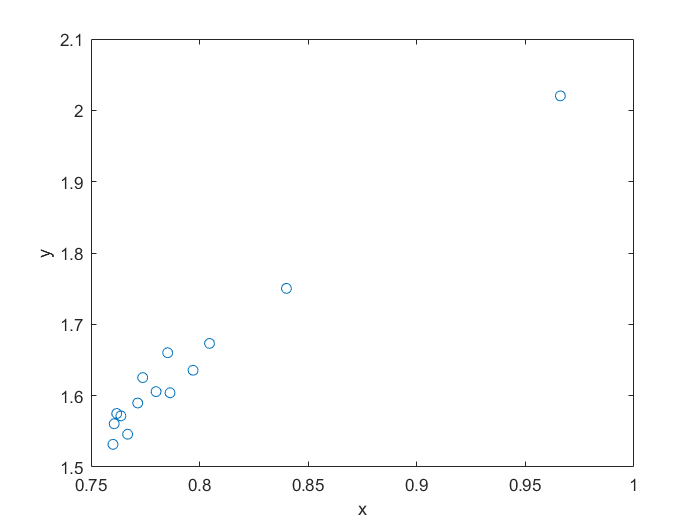

saveas(plt4,'..\img\plot4.png');

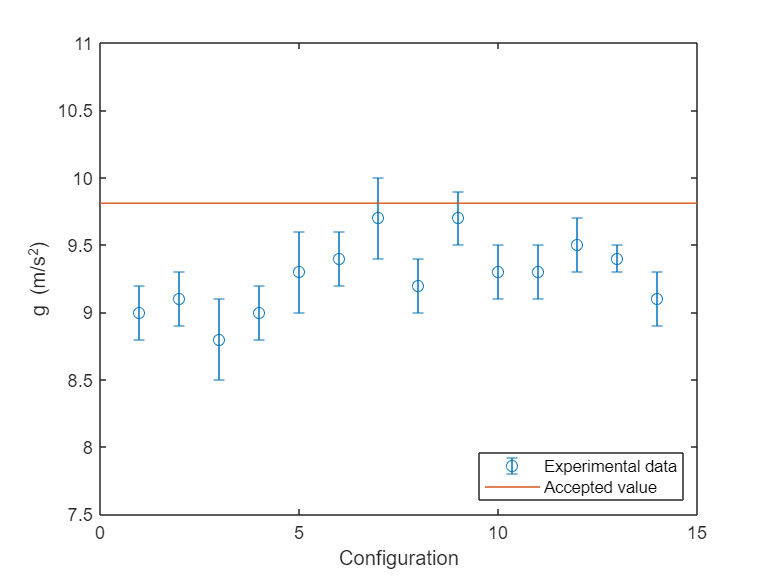

saveas(plt5,'..\img\plot5.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'new_livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);

## Function chi quadro

function chi = chi(x,y,sigma) 
    % x valore atteso
    % y valore osservato
    % sigma deviazione
    for i = 1:length(x)
        c(i) = ((y(i)-x(i))./sigma(i)).^2;
    end
    chi = sum(c);
end

function tt = teot(l,r)
    % l lunghezza pendolo
    % r distanza asse di rotazione - centro di massa
    tt=(2.*pi./sqrt(9.81)).*sqrt(((l.^2)./(12.*r))+r);
end